clc; clear; close all 
s = tf('s');

% parametros PI 
b = 3.235;
r1 = 0.226;
kp = 10;
ki = r1*kp;

% funçao da planta
Gp = b/((s+r1))


Gp =
 
    3.235
  ---------
  s + 0.226
 
Continuous-time transfer function.
Model Properties


% funçao do controlador
Cp = (kp*s+ki)/s


Cp =
 
  10 s + 2.26
  -----------
       s
 
Continuous-time transfer function.
Model Properties



% LGR
G = Gp;
Lp = Gp*Cp


Lp =
 
  32.35 s + 7.311
  ---------------
   s^2 + 0.226 s
 
Continuous-time transfer function.
Model Properties


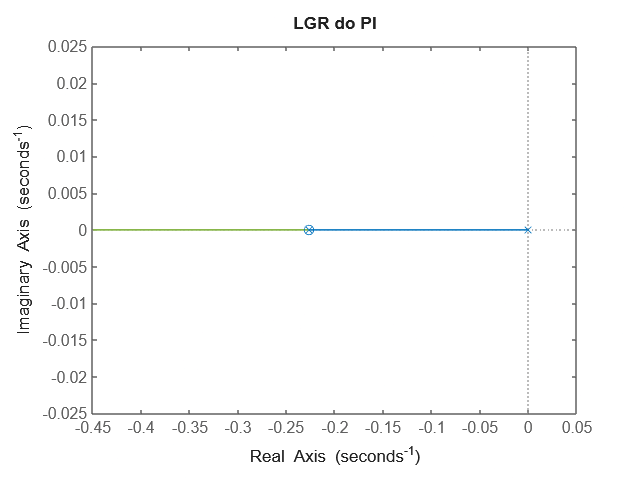

rlocus(Lp)
title('LGR do PI')


% FTMF por cancelamento de polos e zeros
T = b*kp/(s+b*kp)


T =
 
    32.35
  ---------
  s + 32.35
 
Continuous-time transfer function.
Model Properties



% FTMF 
C = kp + ki/s


C =
 
  10 s + 2.26
  -----------
       s
 
Continuous-time transfer function.
Model Properties


L = G*C


L =
 
  32.35 s + 7.311
  ---------------
   s^2 + 0.226 s
 
Continuous-time transfer function.
Model Properties


T_s = L/(1+L)


T_s =
 
    32.35 s^3 + 14.62 s^2 + 1.652 s
  ------------------------------------
  s^4 + 32.8 s^3 + 14.67 s^2 + 1.652 s
 
Continuous-time transfer function.
Model Properties


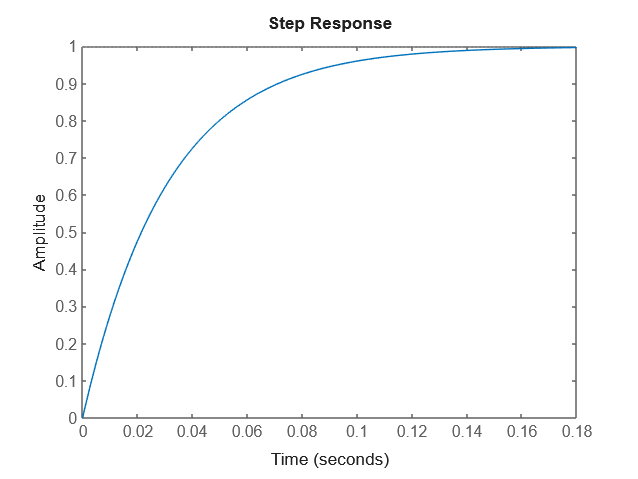


step(T) 

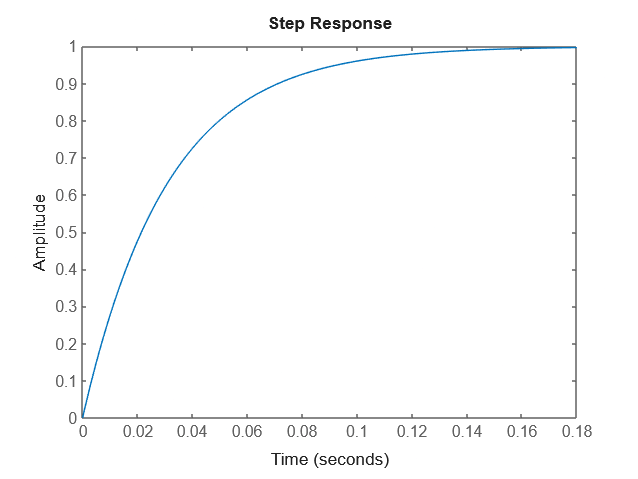

step(T_s)

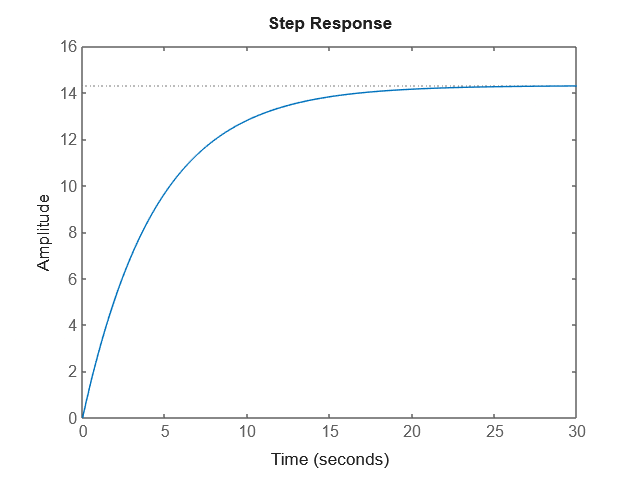

step(Gp)